## Kernel visualization on manipulator POI

clear

% create figure
figure()

% map resolution
resolution = 10

resolution = 10


% Robot Base position
% robot base transformation (move to x - 1m, y - 1m)
Tbase = eye(4);
Tbase(1:2,4) = [1 1]';

%load data
load('C:\Users\Jakob\Documents\GitHub\Gradient-3D\Code\Experiments APF\output_column_spare.mat')

% grid
grid = OctoGrid(2,2,2,10);

display robot with POI

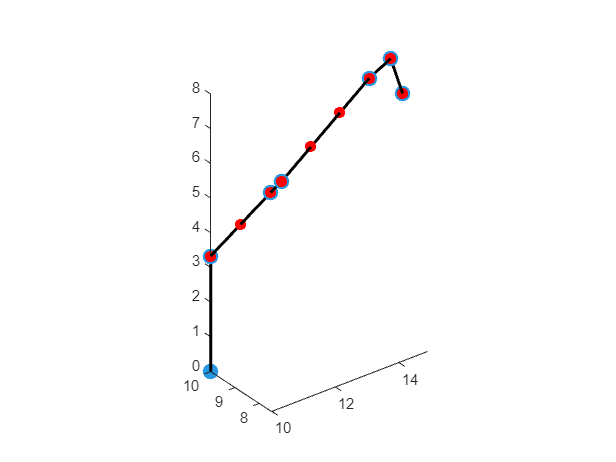

% displayed point
index = 55;

% adjust the length to your preference
arrow_length = 0; 

%% COLORMAP
% ---------------------------------------------------------------
cMap = interp1(0:1,[0 1 0; 1 0 0],linspace(0,1,256));
cMap = cMap.^(1/2.4); % linearize

% calculate transforms from joint positions
[transforms] = GeometricPandaMATLAB(output.joints_positions(:,index), Tbase);

    % figure handles
    points_handles = gobjects(length(transforms),1);
    lines_handles = gobjects(length(transforms),1);
    field_vectors_handles = gobjects(size(output.POI_values{1},2),1);
    field_poi_dots_handles = gobjects(size(output.POI_values{1},2),1);


    
    for i = 1:length(transforms)
        % Plot the transformation frame with thicker lines
%         plotTransforms(transforms(1:3, 4, i)'*resolution, rotm2quat(transforms(1:3, 1:3, i)), 'FrameSize', 0.2);
    
        % Plot the joint point
        points_handles(i) = plot3(transforms(1, 4, i)*resolution, transforms(2, 4, i)*resolution, transforms(3, 4, i)*resolution, 'o', 'MarkerSize', 10, 'MarkerFaceColor', [38/255, 151/255, 224/255], 'MarkerEdgeColor', [38/255, 151/255, 224/255]);
    
        hold on

        % Connect the joint points with thicker lines
        if i > 1
            % Get the previous and current joint positions
            prevPos = transforms(1:3, 4, i-1);
            currPos = transforms(1:3, 4, i);
    
            % Plot a line between the joint positions with thicker lines
            lines_handles(i) = line([prevPos(1), currPos(1)]*resolution, [prevPos(2), currPos(2)]*resolution, [prevPos(3), currPos(3)]*resolution, 'Color', 'k', 'LineWidth', 2);
        end
    end

        % draw APF field
    % ---------------------------------------------------------------

    for i = 1:1:size(output.POI_values{1},2)        
        % plot the arrow
        hold on

        % calculate color
        apf_magnitude = norm([output.POI_values{index}(1,i),output.POI_values{index}(2,i),output.POI_values{index}(3,i)]);
        apf_magnitude_remapped = round(min(apf_magnitude,1)*255 + 1);
        apf_color = cMap(apf_magnitude_remapped,:);

        APF_handles(i) = quiver3(output.POI_locations{index}(1,i)*resolution, output.POI_locations{index}(2,i)*resolution, output.POI_locations{index}(3,i)*resolution, output.POI_values{index}(1,i)*arrow_length, output.POI_values{index}(2,i)*arrow_length, output.POI_values{index}(3,i)*arrow_length, arrow_length/2,  'LineWidth', 2, 'MaxHeadSize', 1, 'Color', apf_color);
   
%         field_poi_dots_handles(i) = scatter3(output.POI_locations{index}(1,i)*resolution, output.POI_locations{index}(2,i)*resolution, output.POI_locations{index}(3,i)*resolution, 'filled', 'MarkerFaceColor', apf_color, 'MarkerEdgeColor', apf_color);
        field_poi_dots_handles(i) = scatter3(output.POI_locations{index}(1,i)*resolution, output.POI_locations{index}(2,i)*resolution, output.POI_locations{index}(3,i)*resolution, 50, 'filled', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'red');

        %         field_poi_dots_handles(i) = scatter3(output.POI_locations{index}(1,i)*resolution, output.POI_locations{index}(2,i)*resolution, output.POI_locations{index}(3,i)*resolution, 'x', 'MarkerEdgeColor', 'red','SizeData', 200,'LineWidth', 2);
    end


    % Set the limits
    xlim([0 200]);   % X-axis limits
    ylim([0 200]);   % Y-axis limits
    zlim([-50 200]);    % Z-axis limits
    axis equal


    
%     % set display properties
%     axis equal
%     view([-180.9 45.0])
%     hold off;


# display kernel around one of the POI

rep_kernels = REP_kernels('linear');

type = 'linear'

sigma = 2

kernel_length = 10

kernel_width = 5

kernel_height = 5

kernel = rep_kernels{2};


point 1


% grid point
grid_point = output.POI_locations{index}(:,1)*10

grid_point =    10.0000
   10.0000
    3.3300



% size
kernel_size = size(kernel);
half_size = floor(kernel_size / 2);

% Calculate x, y, and z ranges for the window while ensuring they are positive and within grid boundaries.
x_cells = round((grid_point(2) - half_size(1)) : (grid_point(2) + half_size(1)) -1) +1; % grid goes y-x-z
y_cells = round((grid_point(1) - half_size(2)) : (grid_point(1) + half_size(2)) -1) +1;
z_cells = round((grid_point(3) - half_size(3)) : (grid_point(3) + half_size(3)) -1) +1;

% kernel indexes
i_kernel_indexes = 1:1:length(x_cells)

i_kernel_indexes =      1     2     3     4     5     6     7     8     9    10


j_kernel_indexes = 1:1:length(y_cells)

j_kernel_indexes =      1     2     3     4


k_kernel_indexes = 1:1:length(z_cells)

k_kernel_indexes =      1     2     3     4




% init every cells in window to occupued by default
window = ones(kernel_size);

% grid goes y,x,z
for i = i_kernel_indexes
    for j = j_kernel_indexes
        for k = k_kernel_indexes

            x = x_cells(i);
            y = y_cells(j);
            z = z_cells(k);

            grid.grid(x,y,z) = 1*abs((kernel(i,j,k)));


        end
    end
end


point 2

% grid point
grid_point = output.POI_locations{index}(:,9)*10

grid_point =    14.6305
    8.6547
    8.0087



% size
kernel_size = size(kernel);
half_size = floor(kernel_size / 2);

% Calculate x, y, and z ranges for the window while ensuring they are positive and within grid boundaries.
x_cells = round((grid_point(2) - half_size(1)) : (grid_point(2) + half_size(1)) -1) +1; % grid goes y-x-z
y_cells = round((grid_point(1) - half_size(2)) : (grid_point(1) + half_size(2)) -1) +1;
z_cells = round((grid_point(3) - half_size(3)) : (grid_point(3) + half_size(3)) -1) +1;

% kernel indexes
i_kernel_indexes = 1:1:length(x_cells)

i_kernel_indexes =      1     2     3     4     5     6     7     8     9    10


j_kernel_indexes = 1:1:length(y_cells)

j_kernel_indexes =      1     2     3     4


k_kernel_indexes = 1:1:length(z_cells)

k_kernel_indexes =      1     2     3     4




% init every cells in window to occupued by default
window = ones(kernel_size);

% grid goes y,x,z
for i = i_kernel_indexes
    for j = j_kernel_indexes
        for k = k_kernel_indexes

            x = x_cells(i);
            y = y_cells(j);
            z = z_cells(k);

            grid.grid(x,y,z) = 1*abs((kernel(i,j,k)));


        end
    end
end


point 3

% grid point
grid_point = output.POI_locations{index}(:,6)*10

grid_point =    11.4723
    7.8107
    6.9584



% size
kernel_size = size(kernel);
half_size = floor(kernel_size / 2);

% Calculate x, y, and z ranges for the window while ensuring they are positive and within grid boundaries.
x_cells = round((grid_point(2) - half_size(1)) : (grid_point(2) + half_size(1)) -1) +1; % grid goes y-x-z
y_cells = round((grid_point(1) - half_size(2)) : (grid_point(1) + half_size(2)) -1) +1;
z_cells = round((grid_point(3) - half_size(3)) : (grid_point(3) + half_size(3)) -1) +1;

% kernel indexes
i_kernel_indexes = 1:1:length(x_cells)

i_kernel_indexes =      1     2     3     4     5     6     7     8     9    10


j_kernel_indexes = 1:1:length(y_cells)

j_kernel_indexes =      1     2     3     4


k_kernel_indexes = 1:1:length(z_cells)

k_kernel_indexes =      1     2     3     4




% init every cells in window to occupued by default
window = ones(kernel_size);

% grid goes y,x,z
for i = i_kernel_indexes
    for j = j_kernel_indexes
        for k = k_kernel_indexes

            x = x_cells(i);
            y = y_cells(j);
            z = z_cells(k);

            grid.grid(x,y,z) = 1*abs((kernel(i,j,k)));


        end
    end
end

% grid.showGridVoxel(grid.grid,'min_display_value',0)
% figure()
grid.showGridVol3D(grid.grid)

ans = struct with fields:
      cdata: [20×20×20 double]
      alpha: []
      xdata: [0 20]
      ydata: [0 20]
      zdata: [0 20]
     parent: [1×1 Axes]
    handles: [1×60 Surface]
    texture: '3D'
        tag: 'vol3d_e5da80cbf220'


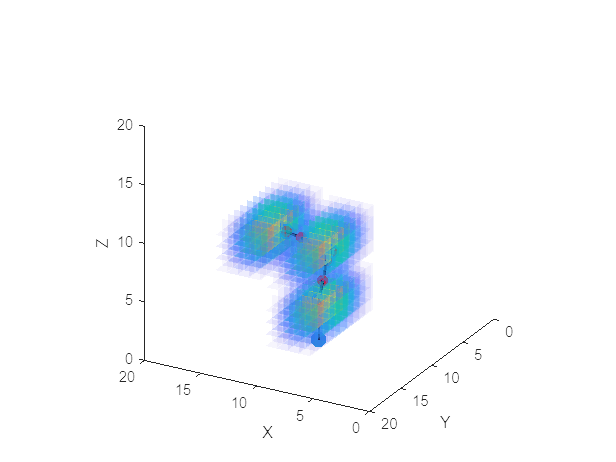

view([-151.0 24.2])